# **Flux Variability Analysis (FVA)**

Maastricht Science Programm Project Period 2020

P3001: Switches and valves of metabolism: Reconstructing metabolic networks from gene expression

Andrea Benedettini, Giulina Lezzoche, Astrid Hofman, Hannah Schultheiss, Natacha Levy, Charlotte Delvaux de Fenffe

%Adapted in June 2020 for PRO3002 Modelling metabolic fluxes in cellular senescence and dilated cardiomyopathy by Charlotte Delvaux de Fenffe

Group: Hannah Schultheiss, Charlotte Delvaux de Fenffe, Sanne Romans, Likhitha Puliyadi, Carmen Kraaijkamp, Catarina Correia

## Introduction

FVA computes the minimum and maximum fluxes for each reaction that are necessary to fulfill the objective function.

FVA can be performed on different subsystems, the subsystem can be changed in line 13. This study performed analysis on four different subsystems: citric acid cycle, fatty acid oxidation, glycolysis and oxidative phosphorylation. The line can be changed to either:

*subSystem= recon22.subSystems(90); (fatty acid oxidation),*

*subSystem= recon22.subSystems(109); (citric acid cycle),*

*subSystem= recon22.subSystems(205); (glycolysis) or*

*subSystem= recon22.subSystems(1584) (Oxidative phosphorilation)*

The code is partially taken from: https://opencobra.github.io/cobratoolbox/latest/tutorials/tutorialFVA.html

initCobraToolbox(false)



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.21.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver('gurobi','all');


 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on the following mac OS versions: macOS 10.12, macOS 10.13.
 > The solver compatibility is not tested with MATLAB R2020a.
 > Solver for LP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on the following mac OS versions: macOS 10.12, macOS 10.13.
 > The solver compatibility is not tested with MATLAB R2020a.
 > Solver for MILP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on the following mac OS versions: macOS 10.12, macOS 10.13.
 > The solver compatibility is not tested with MATLAB R2020a.
 > Solver for QP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on the following mac OS versions: macOS 10.12, macOS 10.13.
 > The solver compatibility is not tested with MATLAB R2020a.
 > Solver for MI


%load the model
load('recon22.mat');

controlModelIMAT = changeObjective(controlModelIMAT, 'DM_atp_c_');
DCMModelIMAT = changeObjective(DCMModelIMAT, 'DM_atp_c_');

modelfva1 = Controlhannahall;%load model Control
modelfva2 = DCMhannahall;%load model DCM

modelfva1.subSystems=string(modelfva1.subSystems);
modelfva2.subSystems=string(modelfva2.subSystems);

% Selecting several reactions of the model that we want to analyse with FVA
subSystem= recon22.subSystems(90);% change this line to investigate a different subsystem

rxnsListC = modelfva1.rxns(ismember(modelfva1.subSystems,subSystem))

rxnsListC = 520×1 cell array
    {'ACACT4p'  }
    {'ACACT5p'  }
    {'ACACT6p'  }
    {'ACACT7p'  }
    {'ACCOACm'  }
    {'ACOAO7p'  }
    {'ADRNCPT1' }
    {'ADRNCPT2' }
    {'ALDD21'   }
    {'ARACHCPT1'}
    {'ARACHCPT2'}
    {'C160CPT1' }
    {'C160CPT2' }
    {'C161CPT1' }
    {'C161CPT12'}
    {'C161CPT2' }
    {'C161CPT22'}
    {'C180CPT1' }
    {'C180CPT2' }
    {'C181CPT1' }
    {'C181CPT2' }
    {'C204CPT1' }
    {'C204CPT2' }
    {'C226CPT1' }
    {'C226CPT2' }
    {'CSNAT2m'  }
    {'CSNAT2x'  }
    {'CSNAT3x'  }
    {'CSNATer'  }
    {'CSNATm'   }


rxnsListDCM = modelfva2.rxns(ismember(modelfva2.subSystems,subSystem))

rxnsListDCM = 516×1 cell array
    {'ACACT4p'  }
    {'ACACT5p'  }
    {'ACACT6p'  }
    {'ACACT7p'  }
    {'ACCOACm'  }
    {'ACOAO7p'  }
    {'ADRNCPT1' }
    {'ADRNCPT2' }
    {'ALDD21'   }
    {'ARACHCPT1'}
    {'ARACHCPT2'}
    {'C160CPT1' }
    {'C160CPT2' }
    {'C161CPT1' }
    {'C161CPT12'}
    {'C161CPT2' }
    {'C161CPT22'}
    {'C180CPT1' }
    {'C180CPT2' }
    {'C181CPT1' }
    {'C181CPT2' }
    {'C204CPT1' }
    {'C204CPT2' }
    {'C226CPT1' }
    {'C226CPT2' }
    {'CSNAT2m'  }
    {'CSNAT2x'  }
    {'CSNAT3x'  }
    {'CSNATer'  }
    {'CSNATm'   }



%remove the genes only present in one set or the other
%rxn only in Control
rxnsListdiffpresCnotD= setdiff(rxnsListC, rxnsListDCM)

rxnsListdiffpresCnotD = 14×1 cell array
    {'C8CRNe'       }
    {'DMHPTCRNCPT2' }
    {'DMHPTCRNt'    }
    {'DMNONCRNCPT2' }
    {'FA140ACPH'    }
    {'FA160ACPH'    }
    {'FACOAL140i'   }
    {'FACOAL206'    }
    {'FAOXC15NADx'  }
    {'FAOXC6C4x'    }
    {'FAOXC9BRC7BRm'}
    {'FCOAH'        }
    {'MCOATA'       }
    {'PHYHx'        }


%rxn only in DCM
rxnsListdiffnotprescontrol= setdiff(rxnsListDCM, rxnsListC)

rxnsListdiffnotprescontrol = 10×1 cell array
    {'DOCO13EFATP'}
    {'FAOXC22C20x'}
    {'FAOXC8C6x'  }
    {'FDH'        }
    {'PCRNtc'     }
    {'RE1519X'    }
    {'RE3626M'    }
    {'r0309'      }
    {'r0434'      }
    {'r0638'      }


%remove the unique rxns
%normally we should have 2 sets of identical rxn, using one or the other
%CF and DF should be the same 
rxnsListCF= setdiff(rxnsListC, rxnsListdiffpresCnotD)

rxnsListCF = 506×1 cell array
    {'2MB2COAc'  }
    {'3HBCOARc'  }
    {'ACACT4p'   }
    {'ACACT5p'   }
    {'ACACT6p'   }
    {'ACACT7p'   }
    {'ACCOACm'   }
    {'ACOAO7p'   }
    {'ADPACDAc'  }
    {'ADPACTD'   }
    {'ADPCOACROT'}
    {'ADPCOAPTE' }
    {'ADRNCPT1'  }
    {'ADRNCPT2'  }
    {'ADRNCRNt'  }
    {'ALDD21'    }
    {'ARACHCPT1' }
    {'ARACHCPT2' }
    {'ARACHCRNt' }
    {'BCRNe'     }
    {'C100CPT1'  }
    {'C102CPT1'  }
    {'C10DCCACT' }
    {'C10DCc'    }
    {'C10OHc'    }
    {'C120CPT1'  }
    {'C121CPT1'  }
    {'C12DCACOT' }
    {'C12DCACT'  }
    {'C12DCTD'   }


rxnsListDF= setdiff(rxnsListDCM, rxnsListdiffnotprescontrol)

rxnsListDF = 506×1 cell array
    {'2MB2COAc'  }
    {'3HBCOARc'  }
    {'ACACT4p'   }
    {'ACACT5p'   }
    {'ACACT6p'   }
    {'ACACT7p'   }
    {'ACCOACm'   }
    {'ACOAO7p'   }
    {'ADPACDAc'  }
    {'ADPACTD'   }
    {'ADPCOACROT'}
    {'ADPCOAPTE' }
    {'ADRNCPT1'  }
    {'ADRNCPT2'  }
    {'ADRNCRNt'  }
    {'ALDD21'    }
    {'ARACHCPT1' }
    {'ARACHCPT2' }
    {'ARACHCRNt' }
    {'BCRNe'     }
    {'C100CPT1'  }
    {'C102CPT1'  }
    {'C10DCCACT' }
    {'C10DCc'    }
    {'C10OHc'    }
    {'C120CPT1'  }
    {'C121CPT1'  }
    {'C12DCACOT' }
    {'C12DCACT'  }
    {'C12DCTD'   }



rxnsListtest =

  0×1 empty cell array



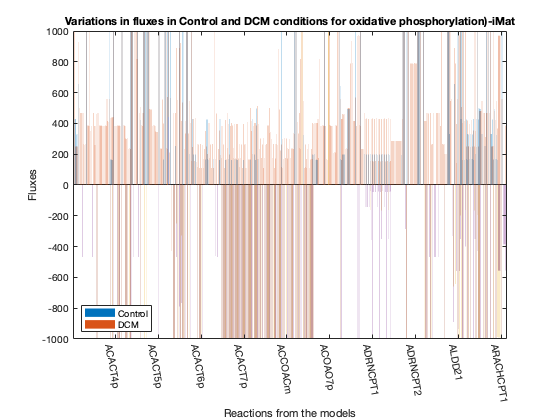


% Run FVA analysis for the model with the constraints that simulates aerobic conditions:
[minFlux1, maxFlux1] = fluxVariability(modelfva1, 100, 'max', rxnsListCF);
[minFlux2, maxFlux2] = fluxVariability(modelfva2, 100, 'max', rxnsListCF);


%making the graph
ymax1 = maxFlux1;
ymin1 = minFlux1;
ymax2 = maxFlux2;
ymin2 = minFlux2;
maxf = table(ymax1, ymax2);
minf = table(ymin1, ymin2);

maxfxs = table2cell(maxf);
minfxs = table2cell(minf);
figure
plot1 = bar(cell2mat(maxfxs(1:end, :)));
hold on
plot2 = bar(cell2mat(minfxs(1:end, :)));
hold off
xticklabels(rxnsList);
set(gca, 'XTickLabelRotation', -80);
yticks([-1000 -800 -600 -400 -200 0 200 400 600 800 1000])
xlabel('Reactions from the models')
ylabel('Fluxes')
legend({'Control', 'DCM'}, 'Location', 'southwest')
title('Variations in fluxes in Control and DCM conditions for oxidative phosphorylation)-iMat')